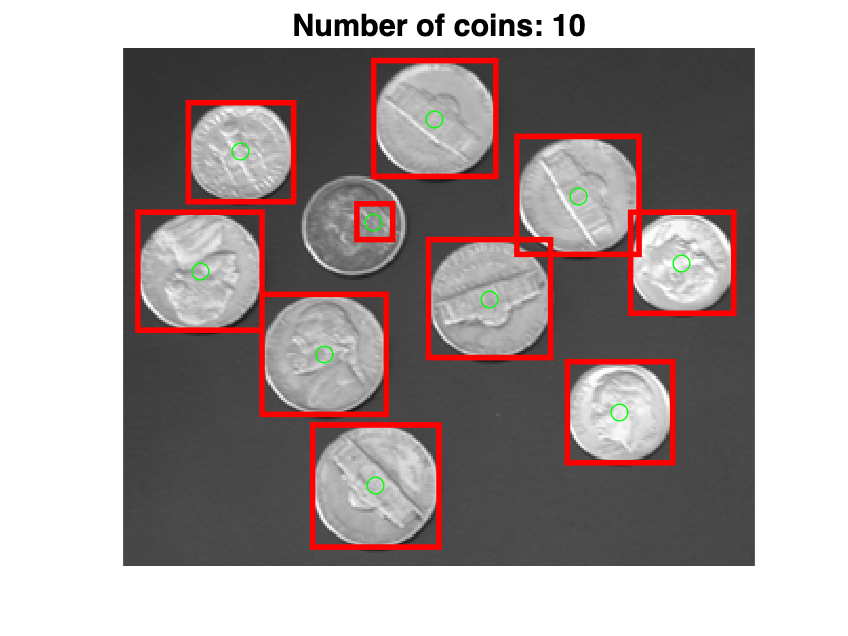

% Step 1: Specify the image file path
img = imread('coins.png');  % Replace with the correct path to your image

% Step 2: Check if the image is RGB, indexed, or grayscale
if size(img, 3) == 3  % RGB image (color)
    gray_img = rgb2gray(img);  % Convert to grayscale
elseif size(img, 3) == 1 && exist('map', 'var') && ~isempty(map)  % Indexed image (2D with colormap)
    gray_img = ind2gray(img, map);  % Convert indexed image to grayscale
else
    gray_img = img;  % Already grayscale image
end

% Step 3: Apply thresholding to get a binary image
bw_img = imbinarize(gray_img);

% Step 4: Perform morphological operations to clean the image
bw_img = imopen(bw_img, strel('disk', 5)); % Remove small noise

% Step 5: Label the connected components (coins)
labeled_img = bwlabel(bw_img);

% Step 6: Get properties of the labeled regions (coins)
stats = regionprops(labeled_img, 'Area', 'Centroid', 'BoundingBox');

% Step 7: Count the number of coins
num_coins = numel(stats);

% Display the results
imshow(img);
hold on;

% Highlight the detected coins
for k = 1:num_coins
    rectangle('Position', stats(k).BoundingBox, 'EdgeColor', 'r', 'LineWidth', 2);
    plot(stats(k).Centroid(1), stats(k).Centroid(2), 'go');
end

% Output the count of coins
title(['Number of coins: ', num2str(num_coins)]);
hold off;